clearvars
close all
clc

## System Parameters

% Cart mass
M = 10;%kg

% Pole mass
m = 2;%kg

% Pole length
L = 4;%meters

% Acceleration due to gravity
g = 9.81; %m/s^2

% Time Step Size
dt = 0.01;

% Time Vector
t_span = [0:dt:10];

## Transfer Function of Plant (Cart Pole)

% Transfer Function of Plant if Pole Angular Position is the output
num_p = 6;
den_p = [-L*(4*M + m),0,6*g*(M+m)];

tf_p = tf(num_p,den_p)


tf_p =
 
        -6
  ---------------
  168 s^2 - 706.3
 
Continuous-time transfer function.



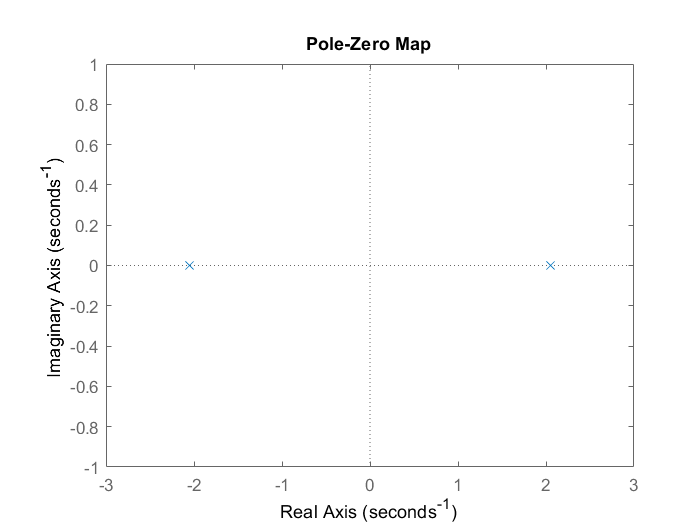


% Poles and Zeros of the unforced/free open loop plant
pzmap(tf_p)

As expected, the unforced Cart Pole plant is unstable.

## PID Controller Controller Gains

Kp = -500;
Kd = -500;
Ki = -10;

% Transfer Function of PID Controller
num_c = [Kd,Kp,Ki];
% num_c = [Kd,Kp];
den_c = [1,0];
% den_c = 1;

tf_c = tf(num_c,den_c)


tf_c =
 
  -500 s^2 - 500 s - 10
  ---------------------
            s
 
Continuous-time transfer function.



**For any external disturbance to the system, the controller block and the plant block will be in a feedback loop.**

% Transfer Function of closed loop system (PID controller + Cart Pole)
tf_cs = feedback(tf_p,tf_c)


tf_cs =
 
                -6 s
  --------------------------------
  168 s^3 + 3000 s^2 + 2294 s + 60
 
Continuous-time transfer function.



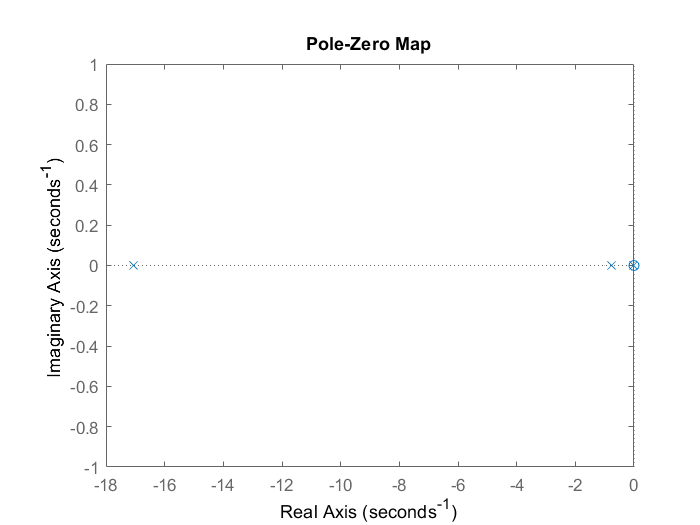


% Pole Locations of the Closed Loop Control System
pzmap(tf_cs)

## Impulse Response of the Closed Loop System

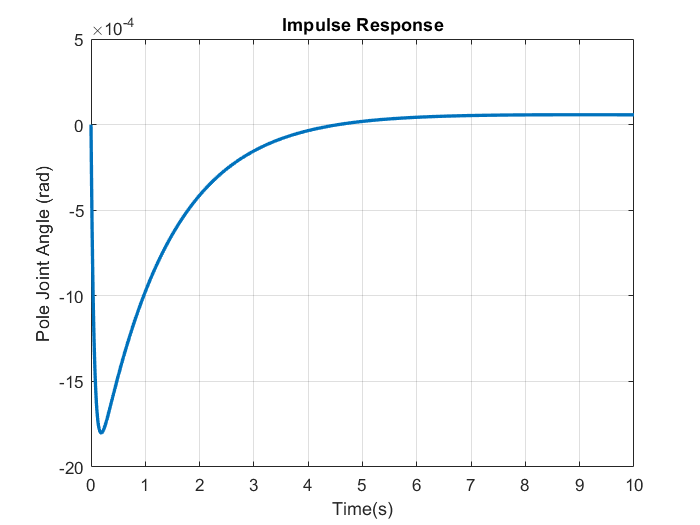

[y,t] = impulse(tf_cs,t_span); % y: closed loop system output (pole angular displacement)

% Plotting the impulse response 
figure
plot(t_span,y,'linewidth',2)
xlabel('Time(s)')
ylabel('Pole Joint Angle (rad)')
title('Impulse Response')
grid on

## Observing Horizontal Displacement of Cart

% Transfer Function of Plant if Cart Position is the    output
num_p1 = [-3*m*L,0,6*(M + m)*g];
den_p1 = [-(m + M)*(4*M + m)*L,0,6*((M + m)^2)*g,0,0];

tf_p1 = tf(num_p1,den_p1)


tf_p1 =
 
    24 s^2 - 706.3
  -------------------
  2016 s^4 - 8476 s^2
 
Continuous-time transfer function.




% Equivalent Transfer Function if Cart Position is the output and
% disturbance force (impulse input) is the system input

tf_cs1 = tf_p1/(1 + tf_c*tf_p)


tf_cs1 =
 
                         4032 s^5 - 1.356e05 s^3 + 4.989e05 s
  -----------------------------------------------------------------------------------
  338688 s^7 + 6.048e06 s^6 + 3.2e06 s^5 - 2.531e07 s^4 - 1.944e07 s^3 - 5.086e05 s^2
 
Continuous-time transfer function.



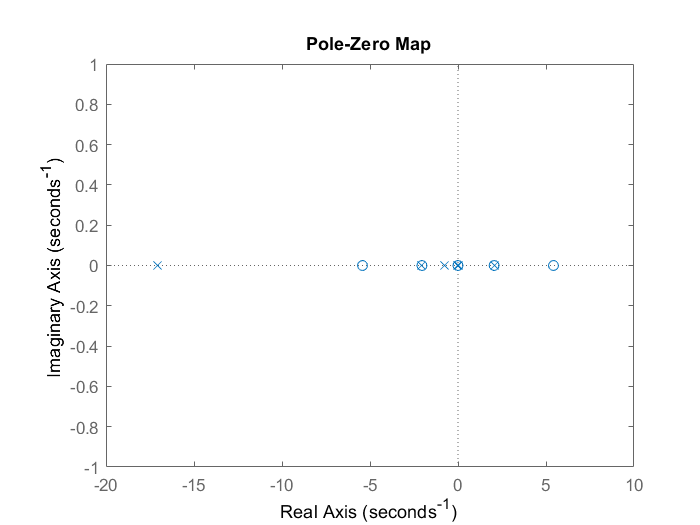


% Poles and Zeros of the equivalent trasnfer function
pzmap(tf_cs1)

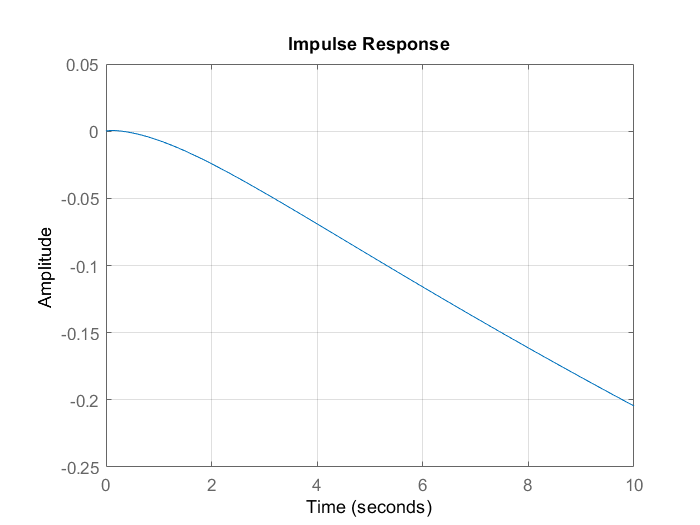


% Uncontrolled Horizontal Position of Cart for Impulse Input as disturbance to system
impulse(tf_cs1,t_span)
grid on